## Taller 11 - Ecuaciones diferenciales

### Modelo de péndulo simple con fuerza tangencial

**Estudiante**: Daniela Córdoba Hamid

**C.C:** 1001015774

**Introducción**

El comportamiento de un péndulo simple puede modelarse mediante ecuaciones diferenciales que describen cómo su posición y velocidad varían en función del tiempo; estas ecuaciones diferenciales son fundamentales para comprender y predecir una amplia gama de sistemas físicos y mecánicos. En este escrito, se abordará la solución de ecuaciones diferenciales para el estudio del movimiento de un péndulo simple, utilizando el software MATLAB; ya que este posibilita resolver diversos tipos de ecuaciones diferenciales de forma eficiente, permitiendo visualizar gráficamente el comportamiento del modelo estudiado, en este caso el péndulo, a lo largo de un rango de tiempo.

**Punto 1**

Uno de los sistemas físicos más sencillos que existen es el péndulo, el cual consiste de una masa suspendida del extremo de un soporte o una cuerda, de tal manera que esta pueda oscilar libremente; cuando este sistema se suelta desde una posición diferente a su posición de equilibrio, la gravedad actúa sobre la masa para atraerla hacia abajo, generando que el sistema realice un movimiento oscilatorio, el cuál sigue un patrón que es posible predecir por medio de ecuaciones diferenciales.

El modelo matemático utilizado para analizar el comportamiento de dicho sistema físico es lo que se conoce como las ecuaciones diferenciales de estado, las cuales en este caso puntual relacionan todas las variables que influyen directamente sobre el péndulo. Las variables de estado pertinentes para este análisis se denominan $\textrm{x₁}$ y $\textrm{x₂}$, donde $\textrm{x₁}$ equivale a la posición angular $\theta$ del péndulo y $\textrm{x₂}$ corresponde a la primera derivada de $\textrm{x₁}$, es decir la velocidad angular $\omega$ del sistema. Lo anterior se puede resumir de la siguiente manera:


$$\textrm{x₁}=\theta$$
            
$$\textrm{x₂}={{\theta \;}^{\prime } }^{\prime } =\omega$$
 

Conociendo entonces las variables de estado con las cuales se trabajará, se establecen las siguientes ecuaciones diferenciales:


$${\textrm{x₁}}^{\prime } =\textrm{x₂}$$
          
$${\textrm{x₂}}^{\prime } =-\frac{g}{l}\textrm{x₁}\;+\;\frac{f}{m}\textrm{x₂}\;+\;\frac{u}{m\;l}$$


Los parámetros a considerar, los cuales como se mencionó previamente afectan directamente el comportamiento del péndulo, son la masa *m*, la longitud *l* de la cuerda o soporte, la fuerza de gravedad *g*, el coeficiente de fricción viscosa *f* y la fuerza externa *u* aplicada sobre el péndulo; ya con estos datos es posible graficar y analizar el comportamiento de un péndulo a lo largo del tiempo.

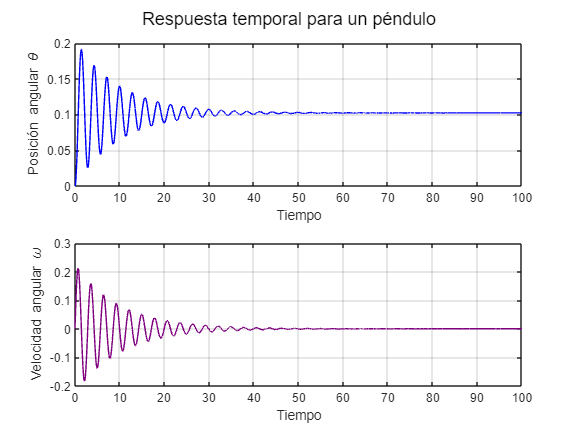

syms X1(t) X2(t) 

% Parámetros del modelo
m = 1; 
g = 9.8; 
l = 2; 
f = 0.2; 
u = 1; %Valor máx de U = 7.5

% Se define la ecuación de estado de segundo orden no lineal
f1 = X2;
f2 = (-g/l)*sin(X1) - (f/m)*X2 + u/(m*l);
funcion = odeFunction([f1 f2],[X1 X2]);

%Parámetros de tiempo para graficar
h = 0.01;
tmax = 100;
tspan = 0:h:tmax; 

%Condiciones iniciales
CI = [0 0]; 

%Resuelve la ecuación de estado
[t,sol] =  ode45(funcion,tspan,CI);

%Gráfica
theta = sol(:,1); 
omega = sol(:,2); 


subplot(2, 1, 1);
plot(t, theta, 'b');
xlabel('Tiempo')
ylabel('Posición angular \theta');
grid on

subplot(2, 1, 2);
plot(t, omega,'Color', [0.5 0 0.5]);
xlabel('Tiempo')
ylabel('Velocidad angular \omega');
grid on

sgtitle('Respuesta temporal para un péndulo')

El movimiento de un péndulo es un movimiento armónico simple, es decir que la posición y la velocidad del sistema tendrán una variación regular a lo largo del tiempo hasta que el péndulo se estabilice y retorne a su posición de reposo. Entonces, al momento de observar las gráficas obtenidas con una fuerza externa $u=1$ es posible apreciar claramente el momento en el cual el sistema retorna a la posición de reposo, por tanto si se desea averiguar con qué valor de fuerza el sistema no podrá estabilizarse, se puede deducir al observar el comportamiento de cualquiera de las gráficas para diferentes valores de dicha fuerza.

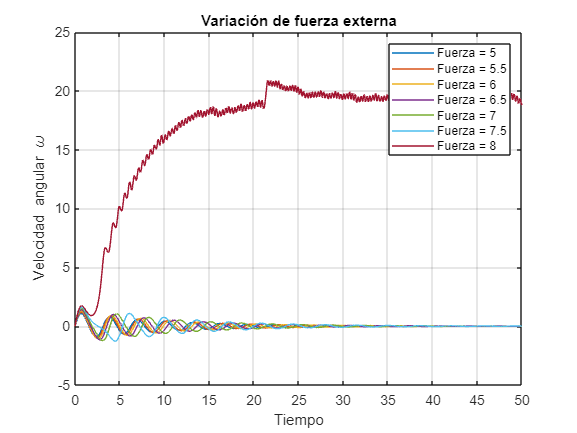

clf
syms X1(t) X2(t)

% Parámetros del modelo
m = 1; 
g = 9.8; 
f = 0.2; 
l = 2;

h = 0.01; 
tmax = 50;
tspan = 0:h:tmax;

u = 5:0.5:8;
N = length(u);

legendLabels = cell(1, N);

for i=1:N
    f1 = X2;
    f2 = (-g/l)*sin(X1) - (f/m)*X2 + u(i)/(m*l);
    funcion = odeFunction([f1 f2],[X1 X2]);
    CI = [0 0]; 
    [t,sol] =  ode45(funcion,tspan,CI);
    omega = sol(:,2);
    plot(t,omega)
    hold on 

    legendLabels{i} = ['Fuerza = ', num2str(u(i))];

end
grid on
legend(legendLabels)
title('Variación de fuerza externa')
xlabel('Tiempo')
ylabel('Velocidad angular \omega')

Al aumentar gradualmente el valor de la fuerza, el péndulo toma cada vez más tiempo en estabilizarse hasta que se llega al valor de 8, donde este ya no se estabiliza y su velocidad aumenta significativamente; esto se debe a que el coeficiente de fricción establecido para este sistema es muy bajo, por tanto al aplicarle una fuerza relativamente grande, el péndulo alcanzará una velocidad que no permitirá que se estabilice al cabo de un tiempo, es decir que rotará indefinidamente; la fuerza máxima que se le puede aplicar al péndulo sin que esto suceda es de 7.5 N.

**Punto 2**

Cuando se analizan sistemas físicos, en la mayoría de los casos se utilizan modelos teóricos que simplifican el comportamiento de dichos sistemas de forma lineal; para este caso en particular se busca graficar la curva de linealidad del sistema del péndulo simple establecido previamente, con el propósito de encontrar qué tan lineal es la relación de alguna de las variables del péndulo con respecto a otra.

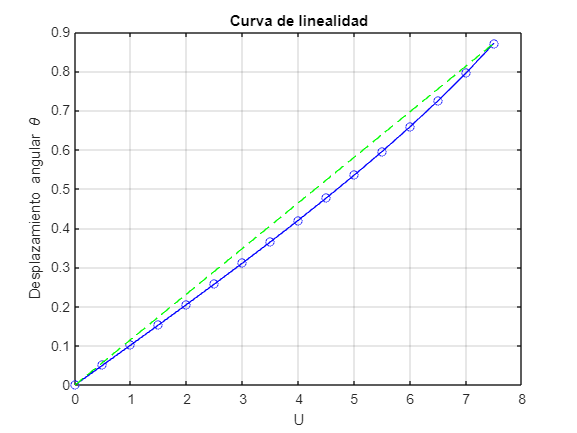

clf
syms X1(t) X2(t)

%Parámetros del modelo
m = 1;
g = 9.8;
l = 2;
f = 0.2;

CI = [0 0];
f1 = X2;

%Analizar theta para diferentes valores de U
rangoU = 0:0.5:7.5;
N = length(rangoU);

h = 0.1;
tmax = 100;
tspan = 0:h:tmax;
theta = zeros(1,N);

for i=1:N
    u = rangoU(i);
    f2 = -(g/l)*sin(X1) -(f/m)*X2 + u/(m*l); 
    funcion = odeFunction([f1 f2],[X1 X2]); 
    [t,sol] = ode45(funcion,tspan,CI);
    theta(i) = sol(end,1);
end

%Gráfica de la curva
plot(rangoU,theta,'b-o',[0 rangoU(end)],[0 theta(end)],'g--')
grid on
xlabel('U')
ylabel('Desplazamiento angular \theta')
title('Curva de linealidad')

Para que dos variables dentro de un sistema posean una relación lineal, es necesario estudiarlo considerando unas condiciones ideales para el funcionamiento de este, como lo es asumir el papel de la fricción dentro del montaje como despreciable; al analizar entonces el péndulo utilizando ecuaciones diferenciales se toma en cuenta la fricción sin importar cuál sea su magnitud, ya que esta puede afectar el comportamiento lineal del sistema. Al graficar la fuerza externa, hasta el valor encontrado previamente donde el péndulo puede estabilizarse, junto con el desplazamiento angular del péndulo, se obtiene que el modelo matemático utilizado, en el cual la fricción juega un papel muy importante, es bastante cercano a presentar una relación lineal entre las variables de desplazamiento angular y la fuerza externa. Lo anterior se debe a que el péndulo en condiciones reales posee un movimiento muy cercano al movimiento armónico simple, el cual sí presenta una relación lineal entre sus variables.

**Punto 3**

El retrato de fase de una ecuación diferencial, en este caso particular de la ecuación utilizada para modelar un péndulo simple, es una representación gráfica de cómo es la evolución del sistema en el espacio de fase, permitiendo obtener una mayor cantidad de información sobre el comportamiento y la dinámica del sistema.

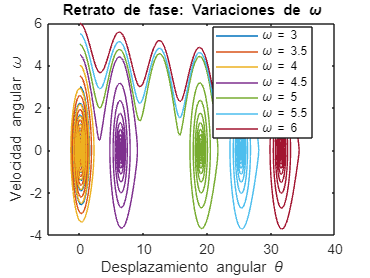

syms X1(t) X2(t)

%Parámetros del modelo
m = 1;
g = 9.8;
l = 2;
f = 0.2;
u = 1;

h = 0.01;
tmax = 100;
tspan = 0:h:tmax;

RangoOmega = 3:0.5:6;
N = length(RangoOmega);

legendLabels = cell(1,N);

for i = 1:N
    CI = [0 RangoOmega(i)]; 

    f1 = X2;
    f2 = -(g/l)*sin(X1) -(f/m)*X2 + u/(m*l);
    funcion = odeFunction([f1 f2],[X1 X2]);

    [t,sol] = ode45(funcion,tspan,CI);
    theta = sol(:,1); 
    omega = sol(:,2);
    plot(theta,omega)
    hold on

    legendLabels{i} = ['\omega = ', num2str(RangoOmega(i))];

end
legend(legendLabels,'Location','best')
xlim([-5 40])
ylim([-4 6])
xlabel('Desplazamiento angular \theta')
ylabel('Velocidad angular \omega')
title('Retrato de fase: Variaciones de \omega')

Ya conociendo los retratos de fase para el péndulo a medida que varía el valor de su velocidad angular inicial, se puede comenzar a analizar para encontrar en qué valores de velocidad el sistema comienza a dar vueltas. Inicialmente se debe plantear un punto de partida, que para simplificar el análisis se tomará con un valor de 0 radianes; ya con esto es posible buscar en el diagrama cuándo se completa un ciclo, debido a que cuando el péndulo da una vuelta, el valor de su velocidad angular disminuye momentáneamente antes de aumentar a un valor cercano al original. Siguiendo entonces este mismo análisis, se puede observar que el péndulo completará una vuelta cuando su velocidad angular inicial corresponda a 4.5 rad/s, y dará tres vueltas cuando dicha velocidad sea igual a 5 rad/s.

**Punto 4**

Posteriormente se busca analizar cómo es el comportamiento del péndulo cuando el valor de su posición angular inicial varía, a diferencia del punto anterior en el cual la variación se presentaba en la velocidad angular inicial, por medio de su retrato de fase.

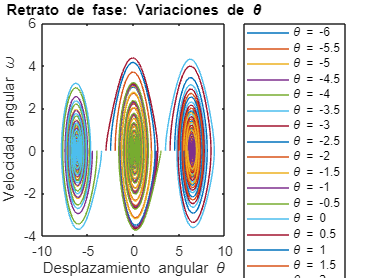

clf
syms X1(t) X2(t)

%Parámetros del modelo
m = 1;
g = 9.8;
l = 2;
f = 0.2;
u = 1;

h = 0.01;
tmax = 100;
tspan = 0:h:tmax;

RangoTheta = -6:0.5:6;
N = length(RangoTheta);

for i = 1:N
    CI = [RangoTheta(i) 0]; 

    f1 = X2;
    f2 = -(g/l)*sin(X1) -(f/m)*X2 + u/(m*l);
    funcion = odeFunction([f1 f2],[X1 X2]);

    [t,sol] = ode45(funcion,tspan,CI);
    theta = sol(:,1); 
    omega = sol(:,2);
    plot(theta,omega)
    hold on
    legendLabels{i} = ['\theta = ', num2str(RangoTheta(i))];

end
legend(legendLabels,'Location','bestoutside')

xlabel('Desplazamiento angular \theta')
ylabel('Velocidad angular \omega')
title('Retrato de fase: Variaciones de \theta')

Inicialmente se puede deducir por medio del retrato de fase obtenido que los puntos de equilibrio para el sistema analizado se ubican en (-6,0), (0,0) y (0,6), y dependiendo del valor establecido inicialmente para la posición angular inicial, el péndulo se estabilizará en alguno de los puntos mencionados previamente. Entonces, para la primera región delimitada por los valores de posición angular -6 y -3, cualquier valor inicial de $\theta$ que se encuentre dentro de este dominio resultará en el péndulo estabilizándose en el primer punto de equilibrio, de igual manera ocurrirá para los valores de posición inicial que se encuentren entre -3 y 3, en los cuales el péndulo se estabilizará en el segundo punto de equilibrio, y en el tercer punto de equilibrio se estabilizarán todos los valores iniciales que se encuentren entre 3 y 6.

**Punto 5**

Ahora se busca analizar qué sucede con el desplazamiento angular del péndulo cuando varía la longitud del soporte o cuerda que lo compone.

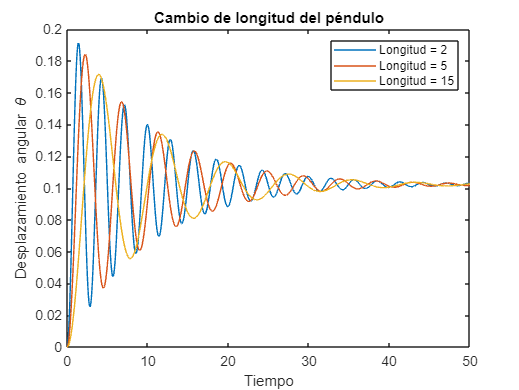

syms X1(t) X2(t)

% Parámetros del modelo
m = 1; 
g = 9.8; 
f = 0.2; 
u = 1;
    
h = 0.01; 
tmax = 50;
tspan = 0:h:tmax;

l = [2 5 15];
N = length(l);

legendLabels = cell(1, N);

for i=1:N
    f1 = X2;
    f2 = (-g/l(i))*sin(X1) - (f/m)*X2 + u/(m*l(i));
    funcion = odeFunction([f1 f2],[X1 X2]);
    CI = [0 0]; 
    [t,sol] =  ode45(funcion,tspan,CI);
    theta = sol(:,1);
    plot(t,theta)
    hold on 

    legendLabels{i} = ['Longitud = ', num2str(l(i))];

end
legend(legendLabels)
title('Cambio de longitud del péndulo')
xlabel('Tiempo')
ylabel('Desplazamiento angular \theta')

La longitud del soporte de un péndulo influye significativamente en el comportamiento de este, ya que es dicho valor el que determina en parte el período y la frecuencia de las oscilaciones. Analizando inicialmente cómo afecta el periodo de oscilación, es necesario tener en cuenta la fórmula de periodo $T=2\pi \sqrt{L\;/\;g}$, donde *L *es el valor correspondiente a dicha longitud; por tanto, la longitud del péndulo es directamente proporcional al periodo de oscilación y esto resultará en que el péndulo se tomará más tiempo para completar un ciclo, como se puede observar en la gráfica cuando la longitud es igual a 15 m. En el caso de la frecuencia, debido a que esta es inversamente proporcional al periodo, al aumentar la longitud del soporte se obtendrá una frecuencia menor, por tanto se dará una menor cantidad de oscilaciones en un mismo lapso de tiempo.

**Punto 6**

Para el siguiente punto lo que se busca analizar es qué sucede con el desplazamiento angular del péndulo cuando varía su masa.

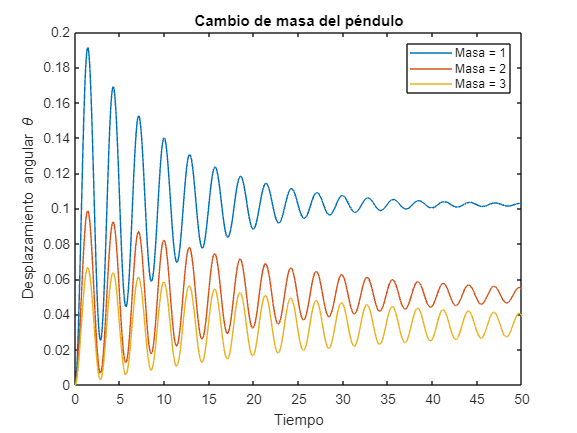

clf
syms X1(t) X2(t)

% Parámetros del modelo
l = 2; 
g = 9.8; 
f = 0.2; 
u = 1;
    
h = 0.01; 
tmax = 50;
tspan = 0:h:tmax;

m = [1 2 3];
N = length(m);

legendLabels = cell(1, N);

for i=1:N
    f1 = X2;
    f2 = -(g/l)*sin(X1) - (f/m(i))*X2 + u/(m(i)*l);
    funcion = odeFunction([f1 f2],[X1 X2]);
    CI = [0 0]; 
    [t,sol] =  ode45(funcion,tspan,CI);
    theta = sol(:,1);
    plot(t,theta)
    hold on 

    legendLabels{i} = ['Masa = ', num2str(m(i))];

end
legend(legendLabels)
title('Cambio de masa del péndulo')
xlabel('Tiempo')
ylabel('Desplazamiento angular \theta')

Similar al caso anterior donde se presentaba una variación en los valores de la longitud del péndulo, cambiar el valor de la masa de este afecta principalmente amplitud de las oscilaciones; ya que al aumentar la masa sin modificar la fuerza aplicada sobre el sistema, el péndulo tiende a oscilar en ángulos más pequeños debido a que la energía aplicada a este no es la suficiente para mantener la amplitud que se obtiene con masas menores. Además de esto, debido a que una mayor masa siempre presentará una mayor inercia, mientras más grande sea el valor de esta, mayor será también el tiempo que el péndulo tome para estabilizarse debido a que será menos sensible a fuerzas externas tales como la fricción.

**Punto 7**

En el siguiente caso se desea analizar es qué sucede con el desplazamiento angular del péndulo cuando varía el coeficiente de fricción.

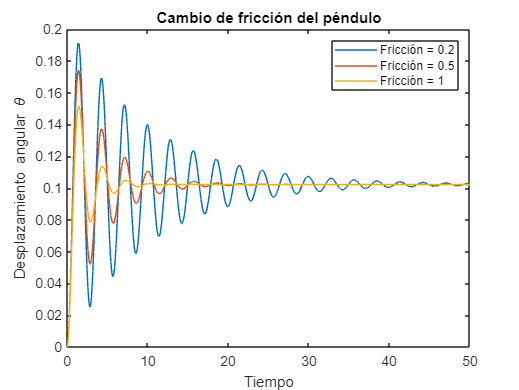

clf
syms X1(t) X2(t)

% Parámetros del modelo
m = 1;
l = 2; 
g = 9.8; 
u = 1;
    
h = 0.01; 
tmax = 50;
tspan = 0:h:tmax;

f = [0.2 0.5 1];
N = length(f);

legendLabels = cell(1, N);

for i=1:N
    f1 = X2;
    f2 = -(g/l)*sin(X1) - (f(i)/m)*X2 + u/(m*l);
    funcion = odeFunction([f1 f2],[X1 X2]);
    CI = [0 0]; 
    [t,sol] =  ode45(funcion,tspan,CI);
    theta = sol(:,1);
    plot(t,theta)
    hold on 

    legendLabels{i} = ['Fricción = ', num2str(f(i))];

end
legend(legendLabels)
title('Cambio de fricción')
xlabel('Tiempo')
ylabel('Desplazamiento angular \theta')

Como se mencionó en el ejercicio anterior, la masa y la fricción pueden afectar significativamente tanto la amplitud como el tiempo que el péndulo toma para estabilizarse. Como se puede observar en la gráfica, si bien la masa en este caso es un valor constante, a medida que aumenta el valor del coeficiente de fricción disminuyen tanto la amplitud como el tiempo de estabilización; esto se debe principalmente a que la fricción sobre el péndulo hace que se reduzca significativamente su velocidad angular, lo que genera que la amplitud máxima a la que se desplaza sea menor, adicional a que la masa para este caso es relativamente pequeña y no posee una inercia que se oponga de gran manera a la acción de la fuerza de fricción.

**Punto 8**

La ecuación diferencial homogénea obtenida de forma analítica fue:


$${{\theta \;}^{\prime } }^{\prime } +\frac{g}{L}\theta =0$$


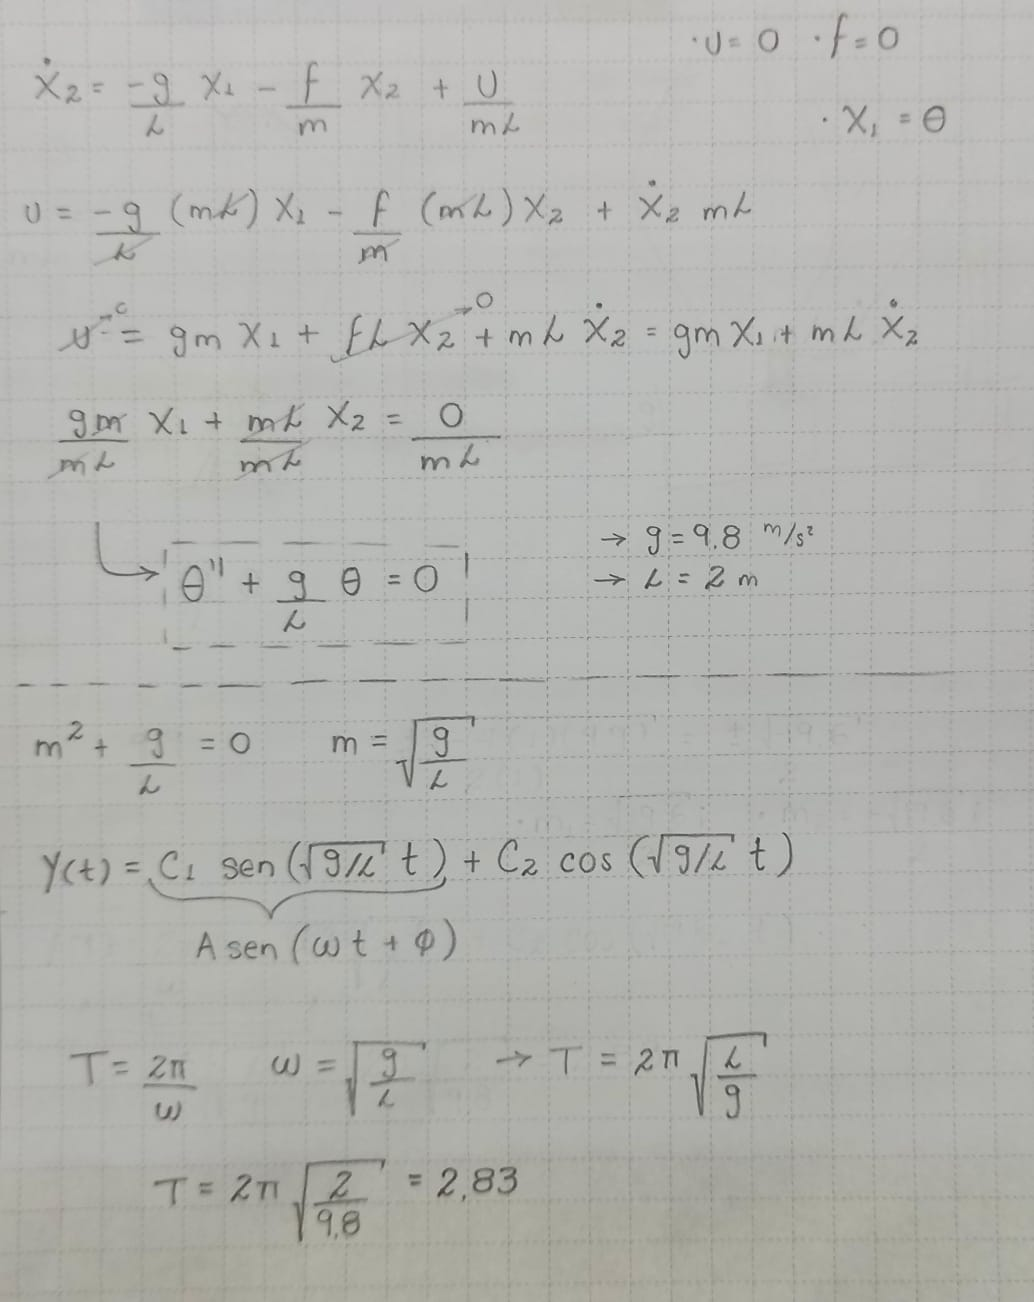

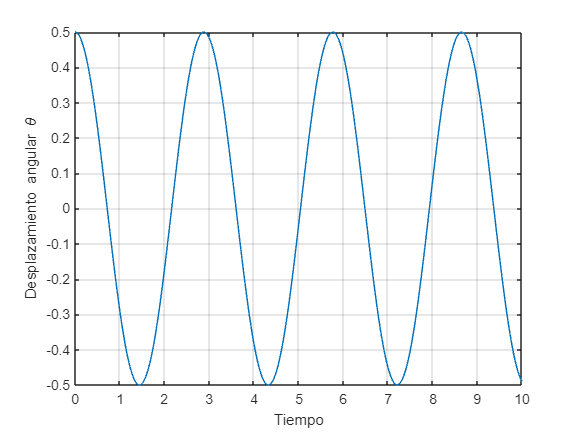

clf
syms X1(t) X2(t) 

%Parámetros del modelo
m = 1; 
g = 9.8; 
l = 2; 
f = 0; 
u = 0; 

f1 = X2;
f2 = -(g/l)*sin(X1) - (f/m)*X2 + u/(m*l);

funcion = odeFunction([f1 f2],[X1 X2]);

h = 0.01; 
tmax = 10;
tspan = 0:h:tmax;

CI = [0.5 0];
[t,sol] =  ode45(funcion,tspan,CI);
theta = sol(:,1);

plot(t,theta)
xlabel('Tiempo')
ylabel('Desplazamiento angular \theta')
grid on

[peaks, peakIndices] = findpeaks(theta);
periodos = diff(t(peakIndices));
PromPeriodo = mean(periodos);

disp(PromPeriodo)

    2.8850



Una de las preguntas propuestas consiste en cómo es posible calcular el valor de la aceleración de la gravedad si se conoce el parámetro de la longitud del péndulo, por lo cual es necesario tener una ecuación que relacione directamente estos dos valores, en particular la fórmula de periodo *T* junto con la fórmula de frecuencia angular.


$$T=\frac{2\pi }{\omega }$$
            
$$\omega =\sqrt{\frac{g}{L}}$$


Con estas dos fórmulas es posible relacionar directamente la gravedad con la longitud del péndulo, resultando en la ecuación:


$$T=2\pi \sqrt{\frac{L}{g}}$$


Por tanto, si se desea calcular el valor de la gravedad, sólo es necesario conocer la longitud del péndulo y su periodo, los cuales son magnitudes que pueden ser medidas experimentalmente. La misma fórmula puede ser utilizada si se desea conocer la longitud cuando ya se tiene el valor de la gravedad.

**Punto 9**

Para el siguiente ejercicio, se busca obtener los valores de la masa y el coeficiente de fricción del péndulo por tanteo cuando ya se conocen varios de los puntos de la gráfica que se debería conseguir. 

syms x1(t) x2(t)

%Valores dados inicialmente
tiempoExp = 0:0.4:10;
thetaExp = [0 0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.1978];

TablaDatos = table(tiempoExp',thetaExp');
ColumnTitle = {'Tiempo experimental', 'Desplazamiento angular experimental'};
TablaDatos.Properties.VariableNames = ColumnTitle;
disp(TablaDatos)

    Tiempo experimental    Desplazamiento angular experimental
    ___________________    ___________________________________

              0                               0               
            0.4                          0.0621               
            0.8                          0.1797               
            1.2                          0.2635               
            1.6                          0.2783               
              2                          0.2414               
            2.4                          0.1932               
            2.8                          0.1656               
            3.2                          0.1667               
            3.6                          0.1852               
              4                          0.2038               
            4.4                          0.2119               
            4.8                          0.2086  

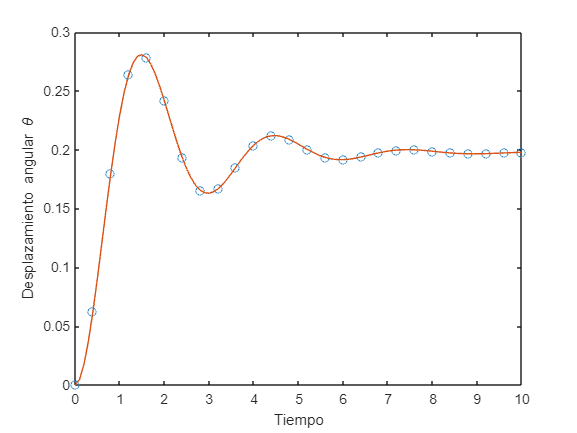

%Parámetros del modelo
g = 9.8; 
l = 2; 
u = 1;

%Parámetros a hallar por tanteo
m = 0.52; 
f = 0.61;

f1 = x2;
f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l);
fun = odeFunction([f1 f2],[x1 x2]);

tspan = 0:0.1:10;

CI = [0 0];
[t,sol] = ode45(fun,tspan,CI); 
theta = sol(:,1); 
figure;
plot(tiempoExp,thetaExp,'o',t,theta)
xlabel('Tiempo')
ylabel('Desplazamiento angular \theta')

Conociendo cómo es el efecto de la masa y la fricción en la gráfica del péndulo, se inicia el tanteo asignando un valor de 0.5 tanto a la masa como al coeficiente de fricción; conociendo entonces que si se desea disminuir la amplitud se debe aumentar la masa y si se desea disminuir el tiempo de estabilización del péndulo se debe de aumentar el valor de la fricción, se comienzan a aumentar gradualmente la masa para acomodar la amplitud de la gráfica, y la fricción para acomodar la estabilización del péndulo para que coincidan con los puntos dados. Finalmente se obtienen valores aproximados de 0.52 kg para la masa y 0.61 kg/s para la fricción.

**Punto 10**

El experimento solicitado fue realizado en uno de los laboratorios de física mecánica de la universidad Eafit, la masa utilizada fue de 0.52 kg y la longitud del soporte rígido corresponde aproximadamente a 0.85 m.

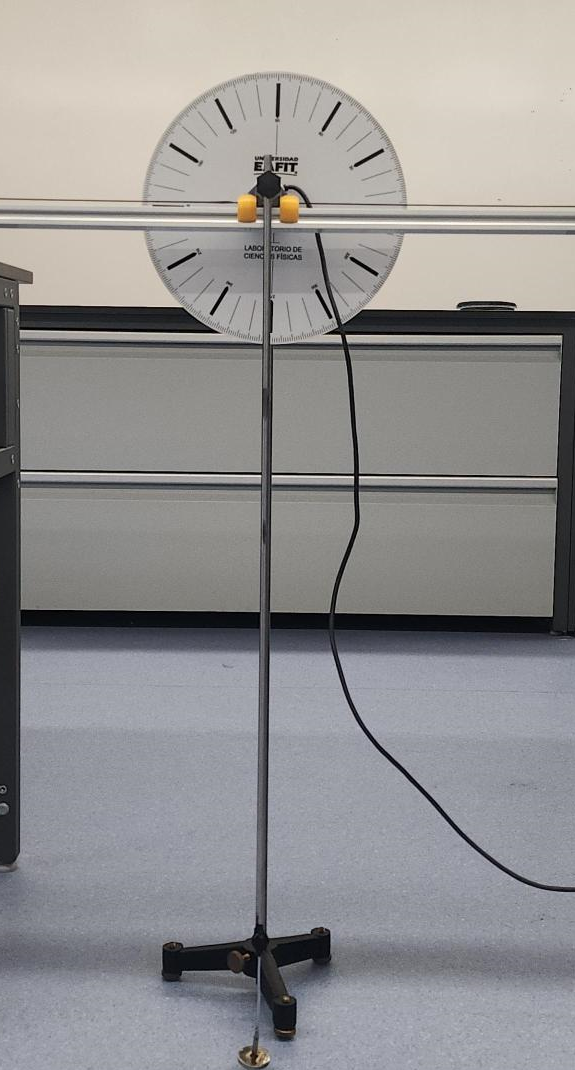

De acuerdo a los videos tomados durante el experimento, se puede estimar un valor para el periodo de oscilación del péndulo de 1.8 segundos, si se asume además un valor de 9.81 m/s² para la gravedad actuando sobre el péndulo, es posible realizar el cálculo experimental de la longitud del soporte.

lteo = 0.85;
g = 9.8;
T = 1.8;

l = (T^2*g)/(4*pi^2)

l = 0.8043

Tomando entonces el valor obtenido como valor experimental, se puede realizar el cálculo del porcentaje de error de la longitud del péndulo.

PorcentajeError = ((lteo-l)/lteo)*100;
Error = num2str(PorcentajeError);

disp(['El porcentaje de error obtenido es de ', Error, '%'])

El porcentaje de error obtenido es de 5.3779%


A diferencia del punto anterior, en este caso no es posible determinar los valores de masa ni fricción, esto debido a que, como fue mencionado previamente, para relacionar directamente los valores conocidos de longitud y gravedad se debe de utilizar la fórmula de periodo de oscilación; sin embargo, esta no incluye los parámetros de masa o fricción, por lo cual no es posible obtenerlos experimentalmente de manera sencilla.

**Conclusión**

Las herramientas computacionales, como el software Matlab, son muy útiles al momento de resolver múltiples ecuaciones diferenciales de sistemas físicos complejos, como lo fue en este caso particular la ecuación que modela el comportamiento de un péndulo; gracias a esta herramienta fue posible explorar cómo la variación en los diversos factores tales como la masa, fricción, longitud y fuerza, puede afectar los resultados del modelo, en especial la amplitud, periodo y estabilidad del péndulo.